## Assigment-Q3, Q4, Q5

#### Q3

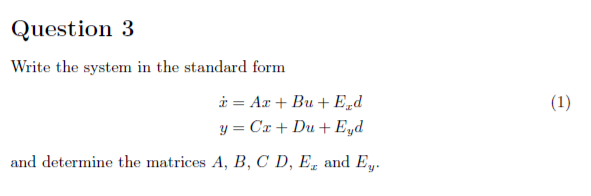

clear all
close all;
clc;

%%Parameters:

syms J_1 J_2 J_3 k_1 k_2 b_1 b_2 b_3

%% State space representation
A = [0 1 0 0 0 0;
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0;
    0 0 0 1  0 0;
    k_1/J_2 0 (-k_1-k_2)/J_2 -b_2/J_2 k_2/J_2 0;
    0 0 0 0 0 1;
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 1/J_1 0 0 0 0]';
C = [ 1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];
D = 0;
E_x = [0 -1/J_1 0 0 0 0]';
E_y = [0 0 0]';


Conclusion:

-As the provided system is already linearised, from the equations, is possible to obtain all the matrices.

#### Q4

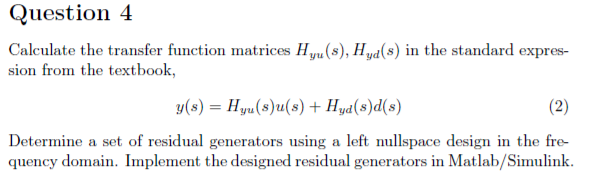

syms s

%Hyu and Hyd

Hyu=C*inv(s*eye(size(A,1))-A)*B+D;
Hyd=C*inv(s*eye(size(A,1))-A)*E_x+E_y

$$Hyd = \begin{array}{l} \left(\begin{array}{c} -\frac{J_{1}\,\left(k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+\sigma_{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2}\right)}{\sigma_{1}}\\ -\frac{J_{1}\,\left(\sigma_{2}+b_{3}\,k_{1}\,s+k_{1}\,k_{2}\right)}{\sigma_{1}}\\ -\frac{J_{1}\,k_{1}\,k_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{J_{1}}\,\left(b_{1}\,k_{1}\,k_{2}\,s+b_{2}\,k_{1}\,k_{2}\,s+b_{3}\,k_{1}\,k_{2}\,s+J_{1}\,J_{2}\,J_{3}\,s^{6}+J_{1}\,J_{2}\,b_{3}\,s^{5}+J_{1}\,J_{3}\,b_{2}\,s^{5}+J_{2}\,J_{3}\,b_{1}\,s^{5}+J_{1}\,J_{2}\,k_{2}\,s^{4}+J_{1}\,J_{3}\,k_{1}\,s^{4}+J_{1}\,J_{3}\,k_{2}\,s^{4}+J_{2}\,J_{3}\,k_{1}\,s^{4}+J_{1}\,b_{2}\,b_{3}\,s^{4}+J_{2}\,b_{1}\,b_{3}\,s^{4}+J_{3}\,b_{1}\,b_{2}\,s^{4}+J_{1}\,b_{2}\,k_{2}\,s^{3}+J_{1}\,b_{3}\,k_{1}\,s^{3}+J_{2}\,b_{1}\,k_{2}\,s^{3}+J_{3}\,b_{1}\,k_{1}\,s^{3}+J_{1}\,b_{3}\,k_{2}\,s^{3}+J_{2}\,b_{3}\,k_{1}\,s^{3}+J_{3}\,b_{1}\,k_{2}\,s^{3}+J_{3}\,b_{2}\,k_{1}\,s^{3}+J_{1}\,k_{1}\,k_{2}\,s^{2}+J_{2}\,k_{1}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,k_{2}\,s^{2}+b_{1}\,b_{2}\,b_{3}\,s^{3}+b_{1}\,b_{2}\,k_{2}\,s^{2}+b_{1}\,b_{3}\,k_{1}\,s^{2}+b_{1}\,b_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,k_{1}\,s^{2}\right)\\ \sigma_{2}=J_{3}\,k_{1}\,s^{2} \end{array}$$


%H matrix

I=eye(size(Hyu,2));
H=[Hyu Hyd;I  zeros(size(Hyu,2),size(Hyd,2))];

%H_sim: simplified H

com_den=gcd(H); %greatest common divisor
H_sim=simplify(H./com_den);

%rank H_sim

rank_H_sim=rank(H_sim)

rank_H_sim = 2


%F matrix: left nullspace matrix

F=null(H_sim')'

$$F = \begin{array}{l} \left(\begin{array}{cccc} -\frac{k_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}} & 1 & 0 & 0\\ -\frac{k_{1}\,k_{2}}{\sigma_{1}} & 0 & 1 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$


%Vry and Vru:

Vry=F(:,1:3);
Vru=F(:,4);

%Residual generators, leftnullspace design, frequency domain:

syms y y1 y2 y3 u
y=[y1;y2;y3];


r=Vry*y+Vru*u

$$r = \begin{array}{l} \left(\begin{array}{c} y_{2}-\frac{k_{1}\,y_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}}\\ y_{3}-\frac{k_{1}\,k_{2}\,y_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$


%Verify design:

verify=simplify(Vry*Hyd)

$$verify = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Conclusion:

-From the linearised system, is possible to obtain Hyu, Hyd.

-Leftnullspace of matrix H, composed by Hyu and Hyd, defines  matrix F.

-The residual generator is obtained from the leftnullspace matrix.

-Vry*Hyd=0, verifies that the residual generator is made from the leftnullspace.

# (WE ARE MISSING THE SIMULINK MODEL!!)

#### Q5

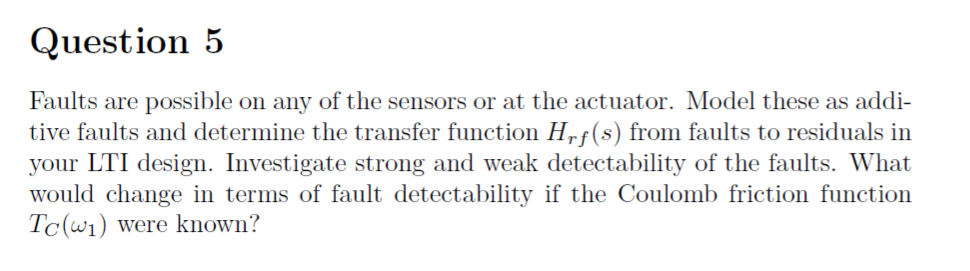

%Fauls present in any of the sensors or at the actuator:
        %f=[f_u;f_y1;f_y2;f_y3]

Fx=[B zeros(size(A,1),3)];      % only present f_u
Fy=[zeros(size(C,1),1) eye(3)]; %only present f_y1;f_y2;f_y3

%Hyf:

Hyf=simplify(C*inv(s*eye(size(A,1))-A)*Fx+Fy);

%Hrf:

Hrf=Vry*Hyf

$$Hrf = \begin{array}{l} \left(\begin{array}{cccc} 0 & -\frac{k_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}} & 1 & 0\\ 0 & -\frac{k_{1}\,k_{2}}{\sigma_{1}} & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$


%Strong and weak detectability for each fault:

%Weak detectability: 

for i=1:4
    if(rank([Hyd Hyf(:,i)])>rank(Hyd))
        if subs(F*[Hyf(:,i); 0], s, 0) == 0
            fprintf('Fault %d is weak detectable\n',i)
        else
            fprintf('Fault %d is strongly detectable\n',i)
        end
    else
        fprintf('Fault %d is NOT detectable\n',i)
    end
end

Fault 1 is NOT detectable


Fault 2 is strongly detectable
Fault 3 is strongly detectable
Fault 4 is strongly detectable
